% Is it possible to
% u(x,n)=atan(x/(n*sqrt(n)))
% apply the theorem on term-by- term differentiation of series?

clear
syms x n;
u(x,n)=atan(x/(n*sqrt(n)))

$$u(x, n) = \mathrm{atan}\left(\frac{x}{n^{3/2}}\right)$$

v(x,n)=x/n^(3/2)

$$v(x, n) = \frac{x}{n^{3/2}}$$


L=limit(u(x,n)/v(x,n),n,inf)

$$L = 1$$

% 1 => according to the second criterion, this series converges

Du(x,n)=diff(u(x,n),x)

$$Du(x, n) = \frac{1}{n^{3/2}\,\left(\frac{x^{2}}{n^{3}}+1\right)}$$

% 1/(n^(3/2)*(x^2/n^3 + 1))

syms i;
for i=1:3
    Du1(i)=Du(x,i);
end
Du1

$$Du1 = \left(\begin{array}{ccc} \frac{1}{x^{2}+1} & \frac{\sqrt{2}}{4\,\left(\frac{x^{2}}{8}+1\right)} & \frac{\sqrt{3}}{9\,\left(\frac{x^{2}}{27}+1\right)} \end{array}\right)$$

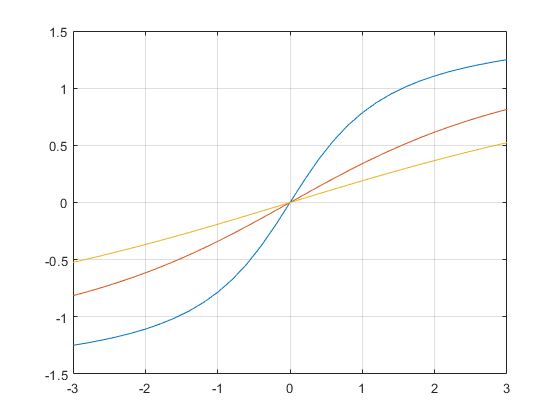

% [ 1/(x^2 + 1), 2^(1/2)/(4*(x^2/8 + 1)), 3^(1/2)/(9*(x^2/27 + 1))]
% All terms of Du(n) is less then terms of series
% 1+1/2^(3/2)+1/3^(3/2)+...

x1=-3:0.2:3;
for i=1:3
    y1=u(x1,i);
    plot(x1,y1)
    hold on
    grid on
end
hold off

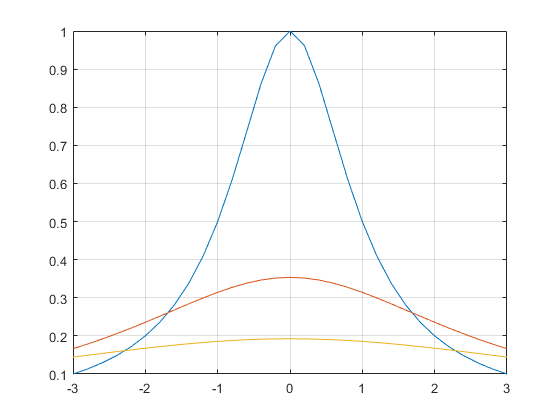


for i=1:3
    y1=Du(x1,i);
    plot(x1,y1)
    hold on
    grid on
end
hold off


% The series composed of the derivatives converges 
% uniformly in the interval (-inf, + inf)
% then
% to a given series one can apply the theorem on 
% the differentiation of series